t1=[0.0,2.0,4.0,6.0,8.0,10.0,12.0,14.0,16.0,19.0,22.0,27.0,32.0,42.0,52.0,62.0,72.0,82.0,92.0,102.0,122.0,142.0,162.0,182.0]

t1 =      0     2     4     6     8    10    12    14    16    19    22    27    32    42    52    62    72    82    92   102   122   142   162   182


Gg=[92.0,350.0,287.0,251.0,240.0,226.0,211.0,205.0,196.0,192.0,172.0,163.0,142.0,124.0,105.0,92.0,84.0,77.0,82.0,81.0,82.0,82.0,85.0,90.0]

Gg =     92   350   287   251   240   226   211   205   196   192   172   163   142   124   105    92    84    77    82    81    82    82    85    90


Ins=[11.0,26.0,130.0,85.0,51.0,49.0,45.0,41.0,35.0,30.0,30.0,27.0,30.0,22.0,15.0,15.0,11.0,10.0,8.0,11.0,7.0,8.0,8.0,7.0]

Ins =     11    26   130    85    51    49    45    41    35    30    30    27    30    22    15    15    11    10     8    11     7     8     8     7


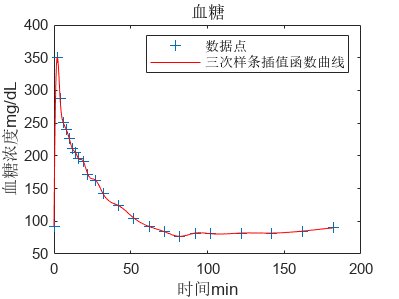

x = t1;
glu = Gg;
x0 = 0;
glu0 = spline(x, glu, x0);
xi = 0:0.1:max(t1);
glui = spline(x, glu, xi);
figure
plot(x, glu, '+', xi, glui, 'r')
legend('数据点', '三次样条插值函数曲线')
ylabel('血糖浓度mg/dL')
xlabel("时间min")
title("血糖")

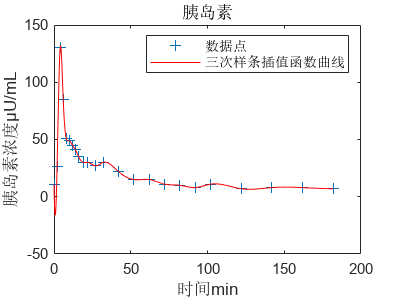

x = t1;
ins = Ins;
x0 = Ins(1);
ins0 = spline(x, ins, x0);
xi = 0:0.1:max(t1);
insi = spline(x, ins, xi);
figure
plot(x, ins, '+', xi, insi, 'r')
legend('数据点', '三次样条插值函数曲线')
ylabel('胰岛素浓度μU/mL')
xlabel("时间min")
title("胰岛素")

max(insi)

ans = 131.8228

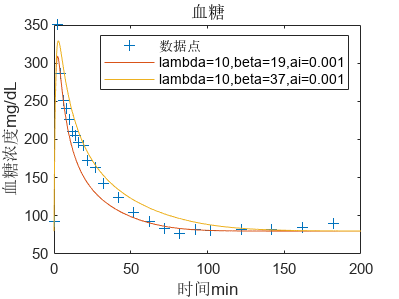

lambda=10;
beta=19;
ai=0.001;
model = 'blood_sugar.slx';  % 替换为您的Simulink模型名称
simOut = sim(model);
lambda=10;
beta=37;
ai=0.001;
simOut1 = sim(model);
figure
plot(x, glu, '+')
hold on
plot(simOut.ScopeData.time,simOut.ScopeData.signals(2).values)
hold on
plot(simOut1.ScopeData.time,simOut1.ScopeData.signals(2).values)
legend('数据点', 'lambda=10,beta=19,ai=0.001','lambda=10,beta=37,ai=0.001')
ylabel('血糖浓度mg/dL')
xlabel("时间min")
title("血糖")
hold off

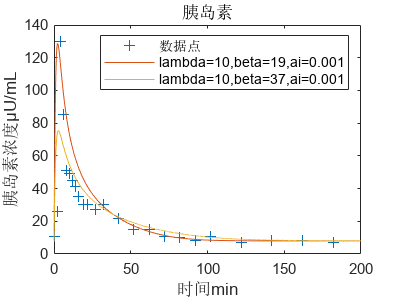

figure
plot(x, ins, '+')
hold on
plot(simOut.ScopeData.time,simOut.ScopeData.signals(1).values)
hold on
plot(simOut1.ScopeData.time,simOut1.ScopeData.signals(1).values)
legend('数据点', 'lambda=10,beta=19,ai=0.001','lambda=10,beta=37,ai=0.001')
ylabel('胰岛素浓度μU/mL')
xlabel("时间min")
title("胰岛素")
hold off

rss1=sum((simOut.ScopeData.signals(2).values(200:10:1821)-b(200:10:1821)).^2);
rss2=sum((simOut.ScopeData.signals(1).values(200:10:1821)-a(200:10:1821)).^2);
rss=rss1*rss2

rss = 2.2475e+07

lambda=10;
beta=20;
ai=0.001;
simOut = sim(model);
a=ins';
b=glu';
rss1=sum((simOut.ScopeData.signals(2).values(t1(2:end))-b).^2);

对于此运算，数组的大小不兼容。

相关文档

rss2=sum((simOut.ScopeData.signals(1).values(t1(2:end))-a).^2);
RSS=rss1*rss2

lambda=5;
beta=10;
ai=0.1;
simOut = sim(model);
a=insi';
b=glui';
rss1=sum((simOut.ScopeData.signals(2).values(100:10:1200)-b(100:10:1200)).^2);
rss2=sum((simOut.ScopeData.signals(1).values(100:10:1200)-a(100:10:1200)).^2);
RSS=rss1+rss2

lambda=10;
beta=20;
ai=0.001;
simOut = sim(model);
a=insi';
b=glui';
rss1=sum((simOut.ScopeData.signals(2).values(100:10:1200)-b(100:10:1200)).^2);
rss2=sum((simOut.ScopeData.signals(1).values(100:10:1200)-a(100:10:1200)).^2);
RSS=rss1+rss2

rsss=[];
N=10;
zh=[10,20,0.001];
for i=1:20
    lambda=i;
    for j=1:50
        beta=j;
        for k=1:5
            ai=0.000001*10^k;
            simOut = sim(model);
            a=insi';
            b=glui';
            rss1=sum(((simOut.ScopeData.signals(2).values(100:10:1200)-b(100:10:1200))/max(glui)).^2);
            rss2=sum(((simOut.ScopeData.signals(1).values(100:10:1200)-a(100:10:1200))/max(insi)).^2);
            rsss((i-1)*50+(j-1)*5+k)=rss1+rss2;
            rss=rss1+rss2;
            if rss<RSS
                zh=[3+i,3*j,0.000001*10^k];
                RSS=rss;
            end
            
        end
    end
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

rsss1=rsss

rsss1 = 1.0e+03 *

    0.4262    0.0748    0.0019    0.0033    0.0036    0.1414    0.0381    0.0008    0.0030    0.0035    0.0818    0.0279    0.0003    0.0028    0.0035    0.0607    0.0244    0.0002    0.0027    0.0035    0.0512    0.0234    0.0003    0.0025    0.0035    0.0463    0.0234    0.0005    0.0024    0.0034    0.0435    0.0239    0.0008    0.0022    0.0034    0.0418    0.0245    0.0012    0.0021    0.0034    0.0408    0.0252    0.0016    0.0020    0.0034    0.0402    0.0259    0.0021    0.0019    0.0034


rsss2=rsss1;
rsss2=rsss2/(10^10);
rsss2(rsss2==0) = max(rsss2);
indices = find(rsss2== min(rsss2))

indices = 348

min(rsss2)

ans = 1.7370e-11

zh

zh =    10.0000   20.0000    0.0010


RSS

RSS = -0.0892